digitDatasetPath = fullfile(matlabroot, 'toolbox', 'nnet', 'nndemos', 'nndatasets', 'DigitDataset');

imds1 = imageDatastore(digitDatasetPath, 'IncludeSubfolders', true, 'LabelSource',"foldernames");

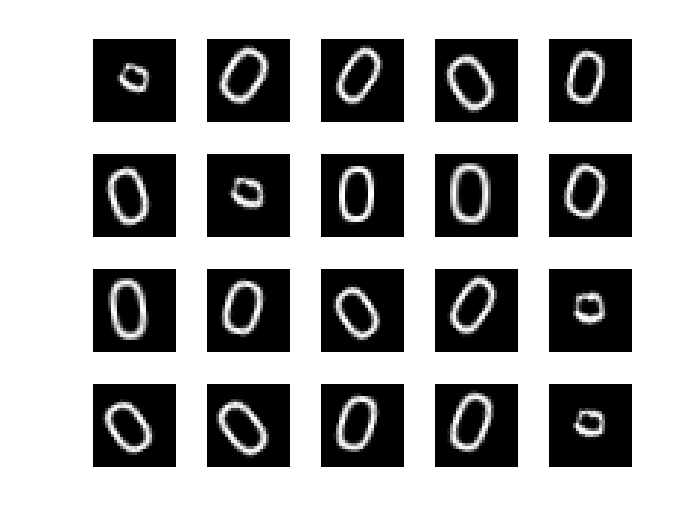

figure;
perm1 = randperm(10000, 20);
for j = 1:20
    subplot(4, 5, j);
    imshow(imds1.Files{perm(j)});
end

labelCount1 = countEachLabel(imds)

labelCount1 = 3×2 table
     Label      Count
    ________    _____

    Broken       20  
    NoDefect     20  
    Spot         20  


img1 = readimage(imds1, 3);
size(img1)

ans =     28    28


numTrainFiles = 750;
[imdsTrain, imdsValidation] = splitEachLabel(imds, numTrainFiles, "randomized");

layers = [
    imageInputLayer([28 28 1]) % if rgb so 1 will be 3 otherwise 1 means grayscale
    
    convolution2dLayer(3, 8, 'Padding', 'same') 
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2, 'Stride', 2)
    
    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'stride', 2)
    
    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
];

options = trainingOptions("sgdm", "InitialLearnRate", 0.01, ...
    'MaxEpochs', 4, "Shuffle", "every-epoch", ...
    "ValidationData", imdsValidation, ...
    "ValidationFrequency", 30, ...
    "Verbose", false, "Plots", 'training-progress');

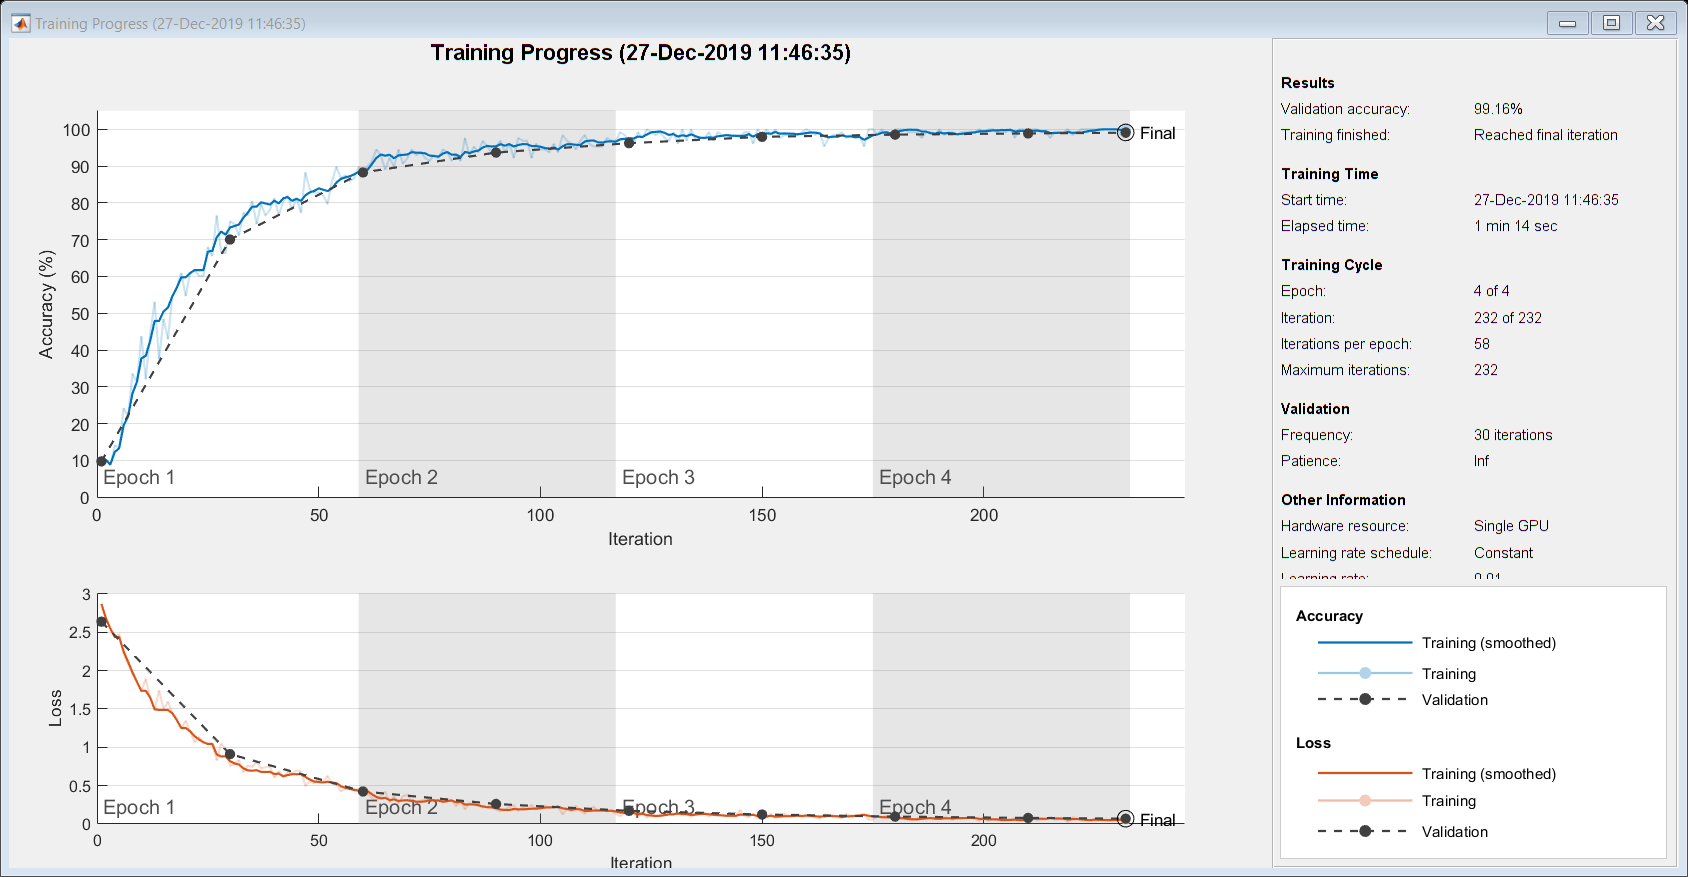

net = trainNetwork(imdsTrain, layers, options);

YPred = classify(net, imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation) / numel(YValidation);

accuracy = 0.9916